# Throughput performance: LoS vs NLoS

## Clear the workspace

clear;
clc;
close all;

## System parameters

numCandiRelays_i = [1152, 2384, 3644];
numCandiRelays_s = ["1152", "2384", "3644"];
DataClass_s = ["Capacity","Paths","Sequence"];
BeamWidth_i = [5,7,9,11,13,15];
seedNum_i = 100; % focusing on 500-599 seeds

## File paths

dataPath_s = '../../Data/';
relayPath_s = 'Relays/';
bsPath_s = 'Base_Stations/';
pathPath_1Mbs_200_s = 'Paths/Single_MBS/200/';
pathPath_1Mbs_300_s = 'Paths/Single_MBS/300/';
pathPath_1Mbs_Ltd_s = 'Paths/Single_MBS_LimitedArea/200/';
pathPath_2Mbs_200_s = 'Paths/Double_MBS/200/';
pathPath_2Mbs_300_s = 'Paths/Double_MBS/300/';
pathPath_2Mbs_Ltd_s = 'Paths/Double_MBS_LimitedArea/200/';

## Read files

relayCoords_f = readRelaysFromFile(strcat(dataPath_s, relayPath_s), 'relay', seedNum_i, numCandiRelays_i);
bsCoords_f = readBssFromFile(strcat(dataPath_s, bsPath_s), seedNum_i);




demand =     7.3175    7.3175
   17.9038   17.9038
   13.0809   23.7626
    5.3656    0.7568
    3.3585    0.3673
    7.9802    7.9802
    3.2952    0.1239
   10.5496    1.9362
    2.4927    0.3187
    5.3661    0.4580


subtree =      2
     1
     1
     2
     3
     2
     3
     1
     4
     2


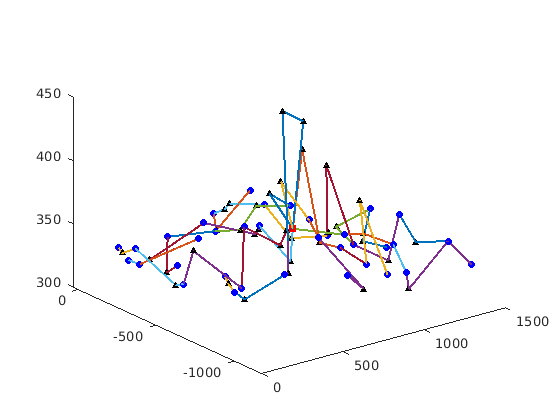

capPath =     9.8622    2.6685   17.2133    2.6685
   10.0755    1.1019   14.7933    1.1019
   10.6751    1.1962   14.9998    1.1962
   10.9397    5.7814   20.0299    5.7814
   10.7936    1.7809   16.0445    1.7809
   10.3366    2.1920   16.6279    2.1920
    9.4146   13.3560   13.3560    0.6071
    9.4185    1.1378   14.8735    1.1378
    9.2638   12.2153   12.2153    0.3699
   14.7568   14.7568   14.7568    1.0859


demand =     7.3175    7.3175
   17.9038   17.9038
   13.0809   23.7626
    5.3656    0.7568
    3.3585    0.3673
    7.9802    7.9802
    3.2952    0.1239
   10.5496    1.9362
    2.4927    0.3187
    5.3661    0.4580


subtree =      2
     1
     1
     2
     3
     2
     3
     1
     4
     2


pathSeqPath = '../../Data/Paths/Single_MBS/200/Data_Results_508_1152_38_5_Sequence.txt';
relayPath = '../../Data/Relays/Data_Relays_Surface_508_0.000100_1.txt';
bsPath = '../../Data/Base_Stations/Data_BSSet_508_1152_200.000000_5.txt';
bsNeighborPath = '../../Data/BS_Neighbors/Data_BSNeighbors_508_38.txt';
pathPath = '../../Data/Paths/Single_MBS/200/Data_Results_508_1152_38_5_Paths.txt';
[capPath, demand, subtree] = getPathInfo(pathSeqPath,relayPath,bsPath,bsNeighborPath,pathPath,true)

## Plot paths

1) Read relays

% fileID = fopen('../../Data/Relays/Data_Relays_Surface_508_0.000100_1.txt');
% relays = fscanf(fileID,'%f,%f,%f',[3,Inf]);
% numRelays = size(relays,2);
% relays = relays';

2) Read BSs

% fileID = fopen('../../Data/Base_Stations/Data_BSSet_508_1152_200.000000_5.txt');
% BSs = fscanf(fileID,'%f,%f,%f',[3,Inf]);
% numBSs = size(BSs,2);
% BSs = BSs';

3) Read path hops

fileID = fopen('../../Data/Paths/Single_MBS/200/Data_Results_508_1152_38_5_Sequence.txt');
hops = fscanf(fileID,'%d\t%d',[2,Inf]);
hops = hops(2,1:end-1);
numNodeHop = hops + 2;
numPaths = size(numNodeHop,2);

4) Read Paths

fileID = fopen('../../Data/Paths/Single_MBS/200/Data_Results_508_1152_38_5_Paths.txt');
paths = fscanf(fileID,'%d');
assert(length(paths) == sum(numNodeHop));
pNodes = zeros(length(paths),3);
for i = 1:length(paths)
    if (paths(i) >= numRelays)
        pNodes(i,:) = BSs(paths(i)-numRelays+1,:);
    else
        pNodes(i,:) = relays(paths(i)+1,:);
    end
end

5) Plot paths

idx = 1;
for i = 1:numPaths
    n = numNodeHop(1,i);
    nodes = pNodes(idx:idx+n-1,:);
    plot3(nodes(:,1),nodes(:,2),nodes(:,3),'LineWidth',1.5); hold on;
    idx = idx + n;
    if i == 1
        scatter3(nodes(1,1),nodes(1,2),nodes(1,3),40,'s','filled','MarkerFaceColor','r');
    else
        scatter3(nodes(end,1),nodes(end,2),nodes(end,3),30,'o','filled','MarkerFaceColor','b');
    end
    if n > 2
        scatter3(nodes(2:end-1,1),nodes(2:end-1,2),nodes(2:end-1,3),20,'^','filled','MarkerFaceColor','k');
    end
end

d_3D_m = 150;
fc_GHz = 60;
B_Hz = 2.16 * 10^9;
pt_dBm = 30;
gt_dBi = 18;
gr_dBi = 18;
pathLoss_LOS_dB = umiStreetPathLoss(d_3D_m, fc_GHz, true);
pathLoss_NLOS_dB = umiStreetPathLoss(d_3D_m, fc_GHz, false);
noise_dBm = noiseWhiteGaussian(B_Hz);
cap_LOS_Gbps = shannonCapacity(pt_dBm, gt_dBi, gr_dBi, pathLoss_LOS_dB, noise_dBm, B_Hz * 10^-9);
cap_NLOS_Gbps = shannonCapacity(pt_dBm, gt_dBi, gr_dBi, pathLoss_NLOS_dB, noise_dBm, B_Hz * 10^-9);